clear all;
close all;
clc;


## Definindo Função

A1 = 1;
A2 = 0;
tau1 = 0.1;
tau2 = 0.9;

T0 = tau1 + tau2;
f0 = inv(T0);
w0 = 2 * pi / T0;

## Cálculo das Projeções

syms t n;

% Projeção em cosseno
Ipc = int(A1*cos(n * w0 * t), t, 0, tau1)

$$Ipc = \frac{\sin\left(\frac{\pi \,n}{5}\right)}{2\,n\,\pi }$$

Inc = int(A2*cos(n * w0 * t), t, tau1, 0)

$$Inc = 0$$


denominador_c = int(cos(n*w0*t)^2, t, 0, T0) %Definir amplitude média

$$denominador\_c = \frac{\sin\left(4\,\pi \,n\right)}{8\,n\,\pi }+\frac{1}{2}$$


an = (Ipc + Inc) / denominador_c

$$an = \frac{\sin\left(\frac{\pi \,n}{5}\right)}{2\,n\,\pi \,\left(\frac{\sin\left(4\,\pi \,n\right)}{8\,n\,\pi }+\frac{1}{2}\right)}$$


% Projeção em seno
Ips = int(A1*sin(n * w0 * t), t, 0, tau1)

$$Ips = \frac{{\sin\left(\frac{\pi \,n}{10}\right)}^{2}}{n\,\pi }$$

Ins = int(A2*sin(n * w0 * t), t, tau1, 0)

$$Ins = 0$$


denominador_s = int(sin(n*w0*t)^2, t, 0, T0) %Definir amplitude média

$$denominador\_s = \frac{1}{2}-\frac{\sin\left(4\,\pi \,n\right)}{8\,n\,\pi }$$


bn = (Ips + Ins) / denominador_s

$$bn = -\frac{{\sin\left(\frac{\pi \,n}{10}\right)}^{2}}{n\,\pi \,\left(\frac{\sin\left(4\,\pi \,n\right)}{8\,n\,\pi }-\frac{1}{2}\right)}$$


% Determinando os valores numéricos
N = 100;
n = [1:1:N];
a = eval(an)

a =     0.1871    0.1514    0.1009    0.0468    0.0000   -0.0312   -0.0432   -0.0378   -0.0208   -0.0000    0.0170    0.0252    0.0233    0.0134    0.0000   -0.0117   -0.0178   -0.0168   -0.0098   -0.0000    0.0089    0.0138    0.0132    0.0078    0.0000   -0.0072   -0.0112   -0.0108   -0.0065   -0.0000    0.0060    0.0095    0.0092    0.0055    0.0000   -0.0052   -0.0082   -0.0080   -0.0048   -0.0000    0.0046    0.0072    0.0070    0.0043    0.0000   -0.0041   -0.0064   -0.0063   -0.0038   -0.0000


b = eval(bn)

b =     0.0608    0.1100    0.1389    0.1440    0.1273    0.0960    0.0595    0.0275    0.0068    0.0000    0.0055    0.0183    0.0321    0.0411    0.0424    0.0360    0.0245    0.0122    0.0032    0.0000    0.0029    0.0100    0.0181    0.0240    0.0255    0.0221    0.0154    0.0079    0.0021    0.0000    0.0020    0.0069    0.0126    0.0169    0.0182    0.0160    0.0113    0.0058    0.0016    0.0000    0.0015    0.0052    0.0097    0.0131    0.0141    0.0125    0.0089    0.0046    0.0012    0.0000


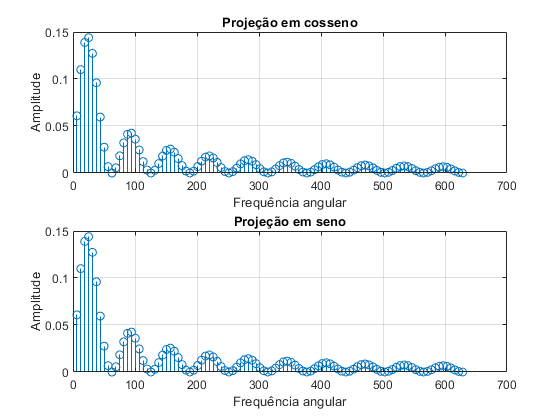


% Visualizando os valores
figure(1)
subplot(2,1,1); stem(n*w0,b);grid;
title('Projeção em cosseno');
xlabel('Frequência angular');
ylabel('Amplitude');

subplot(2,1,2); stem(n*w0,b);grid;
title('Projeção em seno');
xlabel('Frequência angular');
ylabel('Amplitude');


% O sinal somente tem termos (projeções) em seno
% e as projeções em cosseno são nulas


## Síntese de Fourier

auxc = 0;
auxs = 0;
R = T0/1000;          %%% resolução do sinal no tempo
tempo = [0:R:T0];


for k = 1:N
    auxc = auxc + a(k)*cos(n(k)*w0*tempo);
    auxs = auxs + b(k)*sin(n(k)*w0*tempo);
end

a0 = (A1*tau1 + A2*tau2) / T0;
gt = a0 + auxc + auxs      %%% Somatória de Fourier

gt =     0.4951    0.6917    0.8651    0.9951    1.0713    1.0947    1.0765    1.0351    0.9900    0.9574    0.9460    0.9561    0.9808    1.0094    1.0310    1.0389    1.0316    1.0133    0.9917    0.9750    0.9688    0.9747    0.9896    1.0074    1.0215    1.0267    1.0216    1.0087    0.9931    0.9808    0.9761    0.9807    0.9923    1.0065    1.0178    1.0220    1.0178    1.0070    0.9938    0.9831    0.9791    0.9831    0.9934    1.0061    1.0164    1.0203    1.0164    1.0063    0.9938    0.9838


qt = (square(2 * pi * tempo, 10) + 1) / 2;

figure(2);
plot(tempo,gt);grid;
hold;

Current plot held


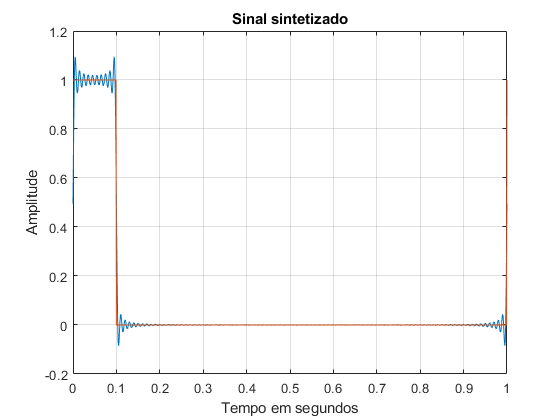

plot(tempo,qt);
title('Sinal sintetizado');
xlabel('Tempo em segundos');
ylabel('Amplitude');


%%% gt não inclui o valor médio, portanto fornece apenas a forma e não a
%%% realidade.